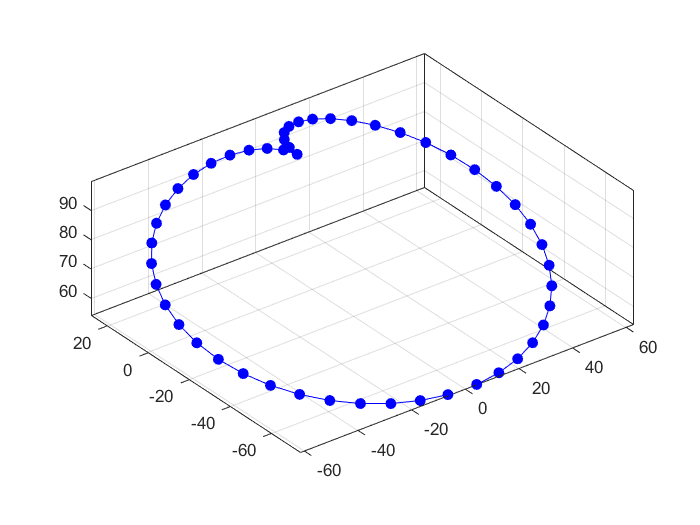

clear all
clc
load ik_net.mat
b = 1;
b_config = [];
b_cartesian = [];

n = zeros(1,50);
n_50 = zeros(1,50);
L_1=50;
L_2=50;

while b <= 50
    % define a circle consist of 50 points
    for b_delta_1 = deg2rad(1):deg2rad(7.18):deg2rad(359)
        %         b_delta_2 = pi/4;%(a)
        %         b_theta_2 = pi/4;%(a)
        %         b_theta_1 = pi/4;%(a)
        %
        %         b_delta_2 = pi/4;%(b)
        %         b_theta_2 = pi/4;%(b)
        %         b_theta_1 = cos(cos(b_delta_1));%(b)
        %
        %         b_delta_2 = 5*pi/6;%(c)
        %         b_theta_2 = pi/4;%(c)
        %         b_theta_1 = cos(cos(2.5*b_delta_1));%(c)
        
        b_delta_2 = pi/4;%(d)
        b_theta_2 = deg2rad(10);%(d)
        b_theta_1 = abs((6/5)*cos(0.5*b_delta_1));%(d)
        
        % position of the second segment
        b_px(b) = sin(b_delta_1)*sin(b_theta_1)*((L_1*tan(b_theta_1/2))/b_theta_1 + (L_2*tan(b_theta_2/2))/b_theta_2) + (L_2*tan(b_theta_2/2)*cos(b_theta_2 - pi/2)*(cos(b_delta_1)*sin(b_delta_2) + cos(b_delta_2)*sin(b_delta_1)*cos(b_theta_1)))/b_theta_2 - (L_2*tan(b_theta_2/2)*sin(b_delta_1)*sin(b_theta_1)*sin(b_theta_2 - pi/2))/b_theta_2;
        b_py(b)=(L_2*tan(b_theta_2/2)*cos(b_theta_2 - pi/2)*(sin(b_delta_1)*sin(b_delta_2) - cos(b_delta_1)*cos(b_delta_2)*cos(b_theta_1)))/b_theta_2 - cos(b_delta_1)*sin(b_theta_1)*((L_1*tan(b_theta_1/2))/b_theta_1 + (L_2*tan(b_theta_2/2))/b_theta_2) + (L_2*tan(b_theta_2/2)*cos(b_delta_1)*sin(b_theta_1)*sin(b_theta_2 - pi/2))/b_theta_2;
        b_pz(b) = cos(b_theta_1)*((L_1*tan(b_theta_1/2))/b_theta_1 + (L_2*tan(b_theta_2/2))/b_theta_2) + (L_1*tan(b_theta_1/2))/b_theta_1 - (L_2*tan(b_theta_2/2)*cos(b_theta_1)*sin(b_theta_2 - pi/2))/b_theta_2 - (L_2*tan(b_theta_2/2)*cos(b_delta_2)*cos(b_theta_2 - pi/2)*sin(b_theta_1))/b_theta_2;
        
        % orientation of the second segment
        b_dir_alpha_Rx(b) = cos(b_theta_2 - pi/2)*(cos(b_delta_1)*sin(b_delta_2) + cos(b_delta_2)*sin(b_delta_1)*cos(b_theta_1)) - sin(b_delta_1)*sin(b_theta_1)*sin(b_theta_2 - pi/2);
        b_dir_beta_Rx(b) = cos(b_theta_2 - pi/2)*(sin(b_delta_1)*sin(b_delta_2) - cos(b_delta_1)*cos(b_delta_2)*cos(b_theta_1)) + cos(b_delta_1)*sin(b_theta_1)*sin(b_theta_2 - pi/2);
        b_dir_gamma_Rx(b) = - cos(b_theta_1)*sin(b_theta_2 - pi/2) - cos(b_delta_2)*cos(b_theta_2 - pi/2)*sin(b_theta_1);
        b_dir_alpha_Ry(b) = - sin(b_theta_2 - pi/2)*(cos(b_delta_1)*sin(b_delta_2) + cos(b_delta_2)*sin(b_delta_1)*cos(b_theta_1)) - sin(b_delta_1)*cos(b_theta_2 - pi/2)*sin(b_theta_1);
        b_dir_beta_Ry(b) =  cos(b_delta_1)*cos(b_theta_2 - pi/2)*sin(b_theta_1) - sin(b_theta_2 - pi/2)*(sin(b_delta_1)*sin(b_delta_2) - cos(b_delta_1)*cos(b_delta_2)*cos(b_theta_1));
        b_dir_gamma_Ry(b) =  cos(b_delta_2)*sin(b_theta_1)*sin(b_theta_2 - pi/2) - cos(b_theta_1)*cos(b_theta_2 - pi/2);
        b_dir_alpha_Rz(b) = cos(b_delta_1)*cos(b_delta_2) - sin(b_delta_1)*sin(b_delta_2)*cos(b_theta_1);
        b_dir_beta_Rz(b) = cos(b_delta_2)*sin(b_delta_1) + cos(b_delta_1)*sin(b_delta_2)*cos(b_theta_1);
        b_dir_gamma_Rz(b) = sin(b_delta_2)*sin(b_theta_1);
        
        
        % covert rotation matrices to euler angles (second segment)
        b_rot = [b_dir_alpha_Rx(end,end) b_dir_alpha_Ry(end,end) b_dir_alpha_Rz(end,end);
            b_dir_beta_Rx(end,end) b_dir_beta_Ry(end,end) b_dir_beta_Rz(end,end);
            b_dir_gamma_Rx(end,end) b_dir_gamma_Ry(end,end) b_dir_gamma_Rz(end,end)];
        
        b_append_eul = rotm2eul(b_rot);
        %b_append_eul = rotm2quat(b_rot);
        
        % data preparation for the neural network
        b_append_config = [b_delta_1 b_theta_1 b_delta_2 b_theta_2];
        
        b_config = [b_config; b_append_config];
        b_append_cartesian = [b_px(b) b_py(b) b_pz(b)];
        b_cartesian = [b_cartesian; b_append_cartesian b_append_eul];
        input = b_cartesian;
        output = [b_config];
        b = b+1;
    end
end

figure
plot3(b_px,b_py,b_pz,'o-','Color','b','MarkerFaceColor','b');

axis equal;
%axis([-80 80 -80 80 0 100]);
box on
hold on
grid on

% use the net to generate the predicted 4-D configration
nn_config_ = net(input');
nn_config = nn_config_'; %% to be used

b = 1;
eul = [];

while b <= 50
    delta_1 = nn_config(b,1);
    theta_1 = nn_config(b,2);
    delta_2 = nn_config(b,3);
    theta_2 = nn_config(b,4);
    
    % position of the second segment
    px(b) = (sin(delta_1)*sin(theta_1)*((L_1*tan(theta_1/2))/theta_1 + (L_2*tan(theta_2/2))/theta_2) + (L_2*tan(theta_2/2)*cos(theta_2 - pi/2)*(cos(delta_1)*sin(delta_2) + cos(delta_2)*sin(delta_1)*cos(theta_1)))/theta_2 - (L_2*tan(theta_2/2)*sin(delta_1)*sin(theta_1)*sin(theta_2 - pi/2))/theta_2);
    py(b)= ((L_2*tan(theta_2/2)*cos(theta_2 - pi/2)*(sin(delta_1)*sin(delta_2) - cos(delta_1)*cos(delta_2)*cos(theta_1)))/theta_2 - cos(delta_1)*sin(theta_1)*((L_1*tan(theta_1/2))/theta_1 + (L_2*tan(theta_2/2))/theta_2) + (L_2*tan(theta_2/2)*cos(delta_1)*sin(theta_1)*sin(theta_2 - pi/2))/theta_2);
    pz(b) = (cos(theta_1)*((L_1*tan(theta_1/2))/theta_1 + (L_2*tan(theta_2/2))/theta_2) + (L_1*tan(theta_1/2))/theta_1 - (L_2*tan(theta_2/2)*cos(theta_1)*sin(theta_2 - pi/2))/theta_2 - (L_2*tan(theta_2/2)*cos(delta_2)*cos(theta_2 - pi/2)*sin(theta_1))/theta_2);
    
    % nn_orientation
    dir_alpha_Rx(b) = cos(theta_2 - pi/2)*(cos(delta_1)*sin(delta_2) + cos(delta_2)*sin(delta_1)*cos(theta_1)) - sin(delta_1)*sin(theta_1)*sin(theta_2 - pi/2);
    dir_beta_Rx(b) = cos(theta_2 - pi/2)*(sin(delta_1)*sin(delta_2) - cos(delta_1)*cos(delta_2)*cos(theta_1)) + cos(delta_1)*sin(theta_1)*sin(theta_2 - pi/2);
    dir_gamma_Rx(b) = - cos(theta_1)*sin(theta_2 - pi/2) - cos(delta_2)*cos(theta_2 - pi/2)*sin(theta_1);
    dir_alpha_Ry(b) = - sin(theta_2 - pi/2)*(cos(delta_1)*sin(delta_2) + cos(delta_2)*sin(delta_1)*cos(theta_1)) - sin(delta_1)*cos(theta_2 - pi/2)*sin(theta_1);
    dir_beta_Ry(b) =  cos(delta_1)*cos(theta_2 - pi/2)*sin(theta_1) - sin(theta_2 - pi/2)*(sin(delta_1)*sin(delta_2) - cos(delta_1)*cos(delta_2)*cos(theta_1));
    dir_gamma_Ry(b) =  cos(delta_2)*sin(theta_1)*sin(theta_2 - pi/2) - cos(theta_1)*cos(theta_2 - pi/2);
    dir_alpha_Rz(b) = cos(delta_1)*cos(delta_2) - sin(delta_1)*sin(delta_2)*cos(theta_1);
    dir_beta_Rz(b) = cos(delta_2)*sin(delta_1) + cos(delta_1)*sin(delta_2)*cos(theta_1);
    dir_gamma_Rz(b) = sin(delta_2)*sin(theta_1);
    
    % covert rotation matrices to euler angles (second segment)
    rot = [dir_alpha_Rx(end,end) dir_alpha_Ry(end,end) dir_alpha_Rz(end,end);
        dir_beta_Rx(end,end) dir_beta_Ry(end,end) dir_beta_Rz(end,end);
        dir_gamma_Rx(end,end) dir_gamma_Ry(end,end) dir_gamma_Rz(end,end)];
    
    append_eul = rotm2eul(rot);
    %append_eul = rotm2quat(rot);
    eul = [eul;append_eul];
    b = b + 1;
end

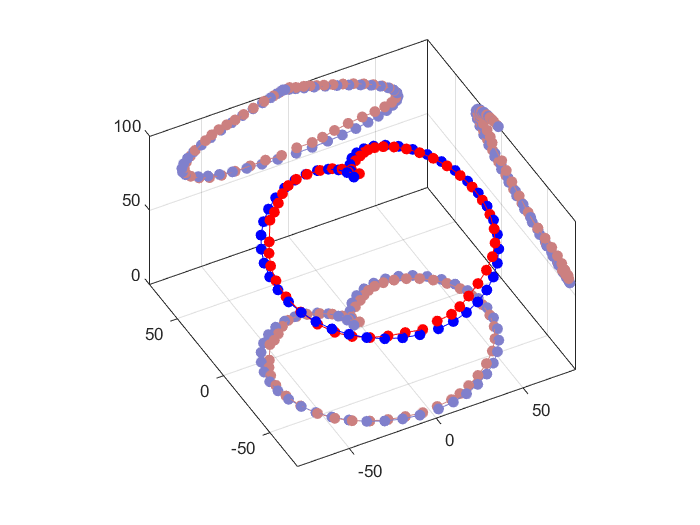

% plot the actual cartesian
figure
plot3(px,py,pz,'o-','Color','r','MarkerFaceColor','r');
hold on
plot3(b_px,b_py,b_pz,'o-','Color','b','MarkerFaceColor','b');
hold on


plot3(px,py,n_50,'o-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot3(b_px,b_py,n,'o-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]');
hold on

plot3(px,n_50+80,pz,'o-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot3(b_px,n+80,b_pz,'o-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]');
hold on

plot3(n_50+80,py,pz,'o-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot3(n+80,b_py,b_pz,'o-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]');
hold on

axis equal;
axis([-80 80 -80 80 0 100]);
box on
hold on
grid on

view([-28 41])

%error
error = [abs(b_px-px); abs(b_py-py); abs(b_pz-pz)];
for r = 1:50
    error_distance(r) = [sqrt(error(1,r)^2+error(2,r)^2+error(3,r)^2)];
end

sorted = sort(error_distance);
max_error = sorted(1,50)

max_error = 8.9451

min_error = sorted(1,1)

min_error = 0.5335

avg_error = mean(sorted)

avg_error = 3.7918

med_error = median(sorted)

med_error = 3.8538

std_error = std(sorted)

std_error = 1.8746

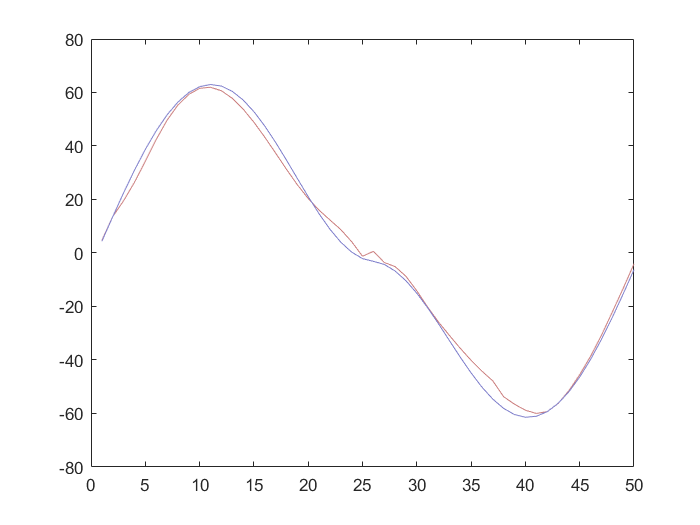

%plot xyz respectively
figurex = [px'];
figurexx = [b_px];

figurey=[py'];
figureyy = [b_py];

figurez = [pz'];
figurezz = [b_pz];

figure
plot(figurex,'-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot(figurexx,'-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]')

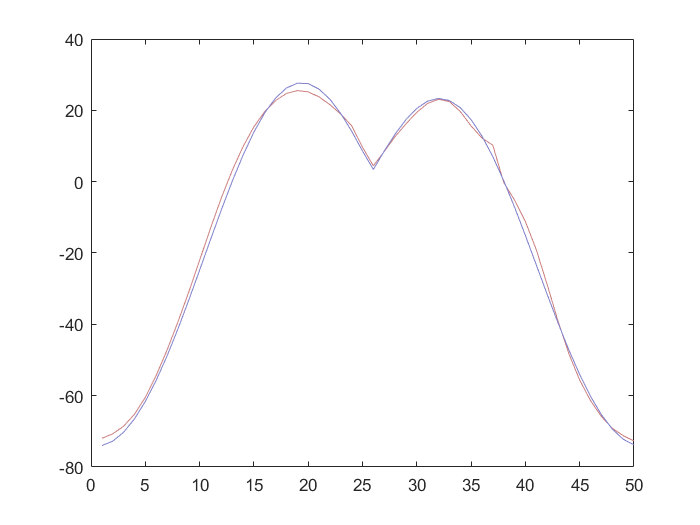


figure
plot(figurey,'-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot(figureyy,'-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]')

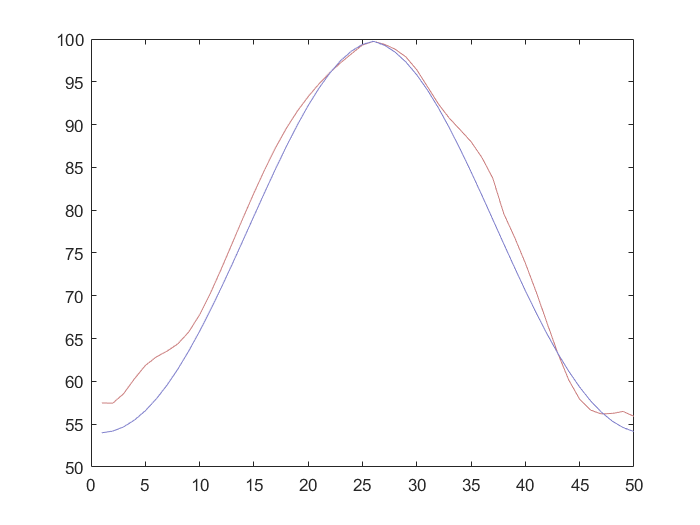


figure
plot(figurez,'-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot(figurezz,'-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]')

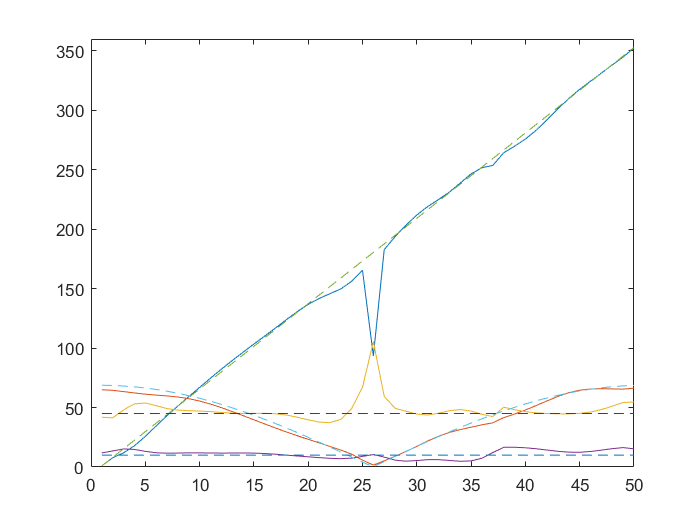

% compare the orientation
figure
deg_nn_config = rad2deg(nn_config);
deg_output = rad2deg(output);
plot(deg_nn_config(1:50,1:4),'-')
hold on
plot(deg_output(1:50,1:4),'--')
hold on
axis([0 50 0 360])